%% Read in csv files and make some vars
run1 = csvread('linear_tof_run1.csv', 1, 0);
run2 = csvread('linear_tof_run2.csv', 1, 0);
cal_lin = csvread('linear_tof_calibration.csv', 1, 0);
cal_tof = csvread('linear_tof_calibration.csv', 1, 1);

%Run1 data
run1_lin = run1(1:6000, 1);
run1_tof = run1(22:9000, 2);

%Run2 data
run2_lin = run2(1:6000, 1);
run2_tof = run2(22:9000, 2);

%Calibration data
cal_tof = cal_tof(23:end, 1);
cal_lin = cal_lin(22:end, 1);

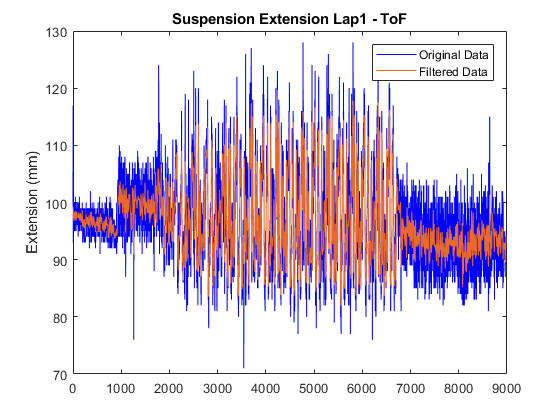

%% ToF data analysis
d = designfilt('lowpassiir','FilterOrder',15, ...
    'HalfPowerFrequency',0.15,'DesignMethod','butter');
run1_tof_filt = filtfilt(d,run1_tof);
run2_tof_filt = filtfilt(d, run2_tof);

%Original vs filtered data run1
figure
plot(run1_tof, 'b')
hold on
plot(run1_tof_filt, 'Color', [ 0.9100 0.4100 0.1700])
axis([0 9000 70 130])
legend('Original Data', 'Filtered Data')
title('Suspension Extension Lap1 - ToF')
ylabel('Extension (mm)')

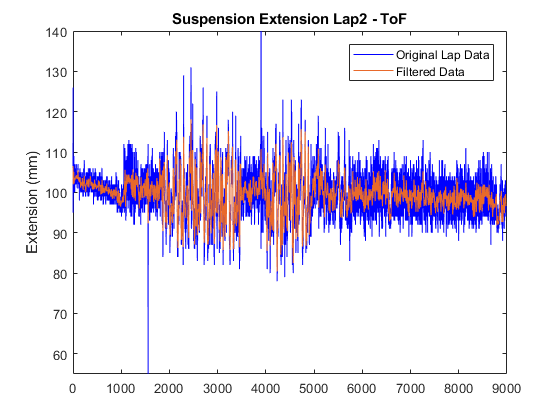


%Original vs filtered data run2
figure
plot(run2_tof, 'b')
hold on
plot(run2_tof_filt, 'Color', [ 0.9100 0.4100 0.1700])
axis([0 9000 55 140])
legend('Original Lap Data', 'Filtered Data')
title('Suspension Extension Lap2 - ToF')
ylabel('Extension (mm)')

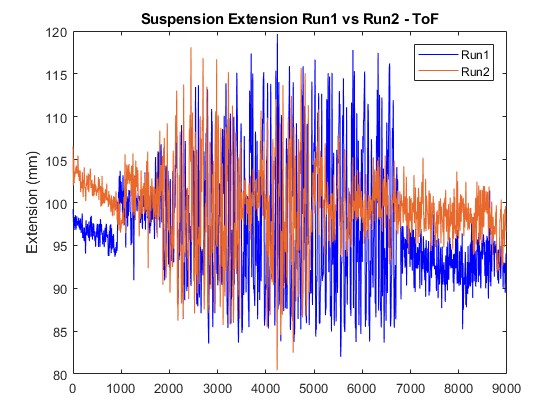


%Filtered data compared
figure
plot(run1_tof_filt, 'b')
hold on
plot(run2_tof_filt, 'Color', [ 0.9100 0.4100 0.1700])
axis([0 9000 80 120])
legend('Run1', 'Run2')
title('Suspension Extension Run1 vs Run2 - ToF')
ylabel('Extension (mm)')

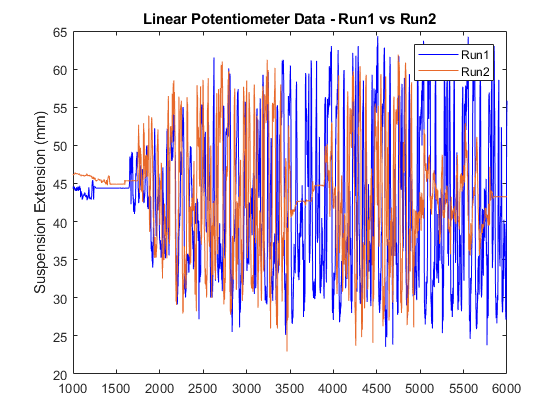

%% Linear potentiometer data analysis
%coefficients determined from original calibration data in excel
lin_grad = 0.0755;
lin_int = 1.6561;

% Convert the read in values to extension numbers (mm)
run1_ext = lin_grad.*run1_lin + lin_int;
run2_ext = lin_grad.*run2_lin + lin_int;

%% Plot the two data sets
figure
plot(run1_ext, 'b')
hold on
plot(run2_ext, 'Color', [ 0.9100 0.4100 0.1700])
axis([1000 6000 20 65])
legend('Run1', 'Run2')
title('Linear Potentiometer Data - Run1 vs Run2')
ylabel('Suspension Extension (mm)')


%% Find some useful info (min, max, diff)
run1_max_ext = max(run1_ext)

run1_max_ext = 64.3211

run1_min_ext = min(run1_ext)

run1_min_ext = 23.5511

run1_ext_diff = run1_max_ext - run1_min_ext

run1_ext_diff = 40.7700


run2_max_ext = max(run2_ext)

run2_max_ext = 61.9051

run2_min_ext = min(run2_ext)

run2_min_ext = 22.9471

run2_ext_diff = run2_max_ext - run1_min_ext

run2_ext_diff = 38.3540

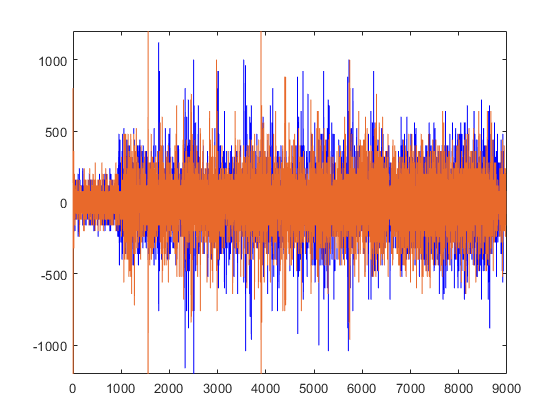

%%Some more analysis velocity
% Set up time sampling stuff
frequency = 40;
sampling_rate = 1/frequency;

% Setup vectors of zeros for differences
run1_tof_diffs = zeros(length(run1_tof)-1, 1);
run2_tof_diffs = zeros(length(run2_tof)-1, 1);

% Get the differences
for i = 1:length(run1_tof_diffs)
    run1_tof_diffs(i,1) = run1_tof(i+1, 1) - run1_tof(i, 1);
    run2_tof_diffs(i, 1) = run2_tof(i+1, 1) - run2_tof(i, 1);
end

% Get velocities
run1_tof_vels = zeros(length(run1_tof_diffs), 1);
run2_tof_vels = zeros(length(run2_tof_diffs), 1);

for i = 1:length(run1_tof_diffs)
    run1_tof_vels(i, 1) = run1_tof_diffs(i, 1) / sampling_rate;
    run2_tof_vels(i, 1) = run2_tof_diffs(i, 1) / sampling_rate;
end

figure
plot(run1_tof_vels, 'b')
hold on
plot(run2_tof_vels, 'Color', [ 0.9100 0.4100 0.1700])
axis([0 9000 -1200 1200])

%% Compare linear and tofs on same scale
med_tof = median(cal_tof)

med_tof = 119

med_lin = lin_grad*median(cal_lin) + lin_int

med_lin = 66.6616

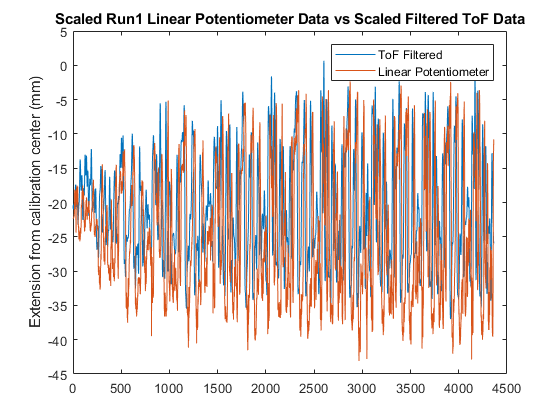


run1_tof_scaled = run1_tof_filt(1638:6000) - med_tof;
run1_lin_scaled = run1_ext(1638:6000) - med_lin;

run2_tof_scaled = run2_tof_filt(1719:5817) - med_tof +20;
run2_lin_scaled = run2_ext(1719:5817) - med_lin +20;

figure
plot(run1_tof_scaled)
hold on
plot(run1_lin_scaled)
title('Scaled Run1 Linear Potentiometer Data vs Scaled Filtered ToF Data')
ylabel('Extension from calibration center (mm)')
legend('ToF Filtered', 'Linear Potentiometer')

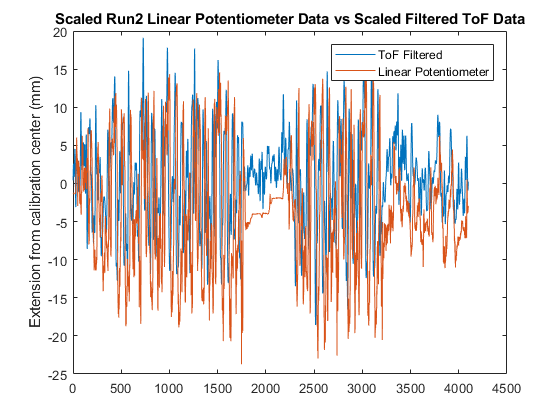


figure
plot(run2_tof_scaled)
hold on
plot(run2_lin_scaled)
title('Scaled Run2 Linear Potentiometer Data vs Scaled Filtered ToF Data')
ylabel('Extension from calibration center (mm)')
legend('ToF Filtered', 'Linear Potentiometer')

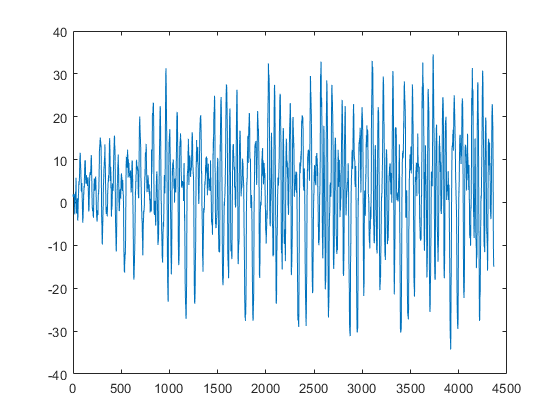


% Compare their differences/similarity
l1 = length(run1_tof_scaled);
l2 = length(run2_tof_scaled);

% Get differences between the ToF and Linear Pot scaled data
run1_lin_tof_diffs = zeros(l1, 1);

for i = 1:l1
    run1_lin_tof_diffs(i,1) = run1_tof_scaled(i,1) - run1_lin_scaled(i,1);
end

run2_lin_tof_diffs = zeros(l2, 1);

for i = 1:l2
   run2_lin_tof_diffs(i,1) = run2_tof_scaled(i,1) - run2_lin_scaled(i,1); 
end

% plot these differences
figure
plot(run1_lin_tof_diffs)

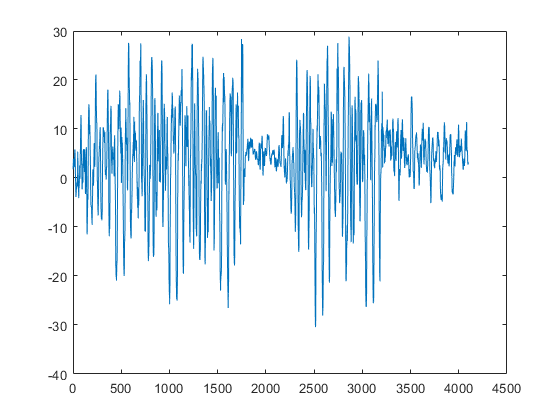


figure()
plot(run2_lin_tof_diffs)


% Get the median, mean and get that % diff between the two for run1 and 2 
% not sure if this is a valid statistical measure
run1_lin_tof_diffs_med = median(run1_lin_tof_diffs)

run1_lin_tof_diffs_med = 4.7106

run1_lin_tof_diffs_avg = mean(run1_lin_tof_diffs)

run1_lin_tof_diffs_avg = 3.5211

run1_percent_diff = 1 - run1_lin_tof_diffs_avg / run1_lin_tof_diffs_med

run1_percent_diff = 0.2525


run2_lin_tof_diffs_med = median(run2_lin_tof_diffs)

run2_lin_tof_diffs_med = 4.8389

run2_lin_tof_diffs_avg = mean(run2_lin_tof_diffs)

run2_lin_tof_diffs_avg = 3.9919

run2_percent_diff = 1 - run2_lin_tof_diffs_avg / run2_lin_tof_diffs_med

run2_percent_diff = 0.1750